Leaf Disc evaluation for 'batch processing'

The scaling created from the first image will be applied to all images of the same folder.

Select image folder, create result folders

disp('Load the images');

Load the images


place = uigetdir;
files = dir(place);


folder_name = ['\results'];                             % change / to \ when using Mac 
mkdir(place,folder_name);

folder_name_control_images = ['\results\control_images'];      
mkdir(place,folder_name_control_images);

folder_name_tables = ['\results\tables'];      
mkdir(place,folder_name_tables);



start image processing

Changes: 

Edge detection based on Prewitt method

New mask, does not use full circles anymore.

Circularity added as output value.

'Chromadapt' function for grey value normalisation.

Scaling implemented.

Image size normalized to 2048x1536 px

image_name = 'IMG_1911_Tn2B_0.JPG'

image_name = 'IMG_1912_Tn2C_0.JPG'

image_name = 'IMG_1913_Tn2D_0.JPG'

image_name = 'IMG_2266_Tn3B_0.JPG'

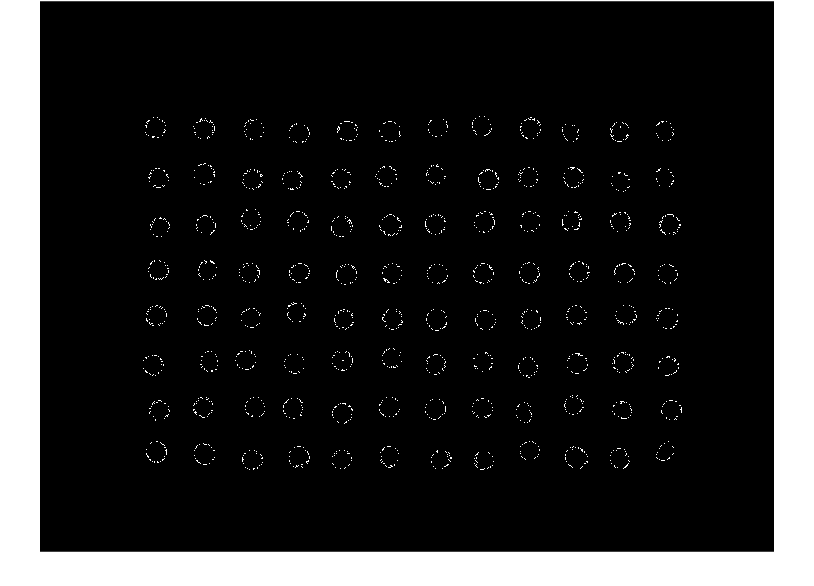


this_value = 1;
% loop for fileloading and processing
for i = 3:numel(files)
    
    % look for .jpg files the imread function can also process .png files.
    % So if your images are .png, just enter it in the row below, replacing '.jpg' 
    if contains(files(i).name, ".jpg") ==1 || contains(files(i).name, ".JPG") ==1
        filename_full = [place, '\', files(i).name]; 
        image_rgb = imread(filename_full);
        image_name = files(i).name;

        %color normalisation
        A_lin = rgb2lin(image_rgb);
        percentiles = 20;
        illuminant = illumgray(A_lin,percentiles);
        image_rgb = chromadapt(A_lin,illuminant,'ColorSpace','linear-rgb');

         %image is scaled to optimized conditions 
        if length(image_rgb) ~= 2048 || height(image_rgb) ~= 1536 
            image_rgb = imresize(image_rgb,[1536,2048]);
        end
        
        if this_value == 1; [single_pixel] = leaf_scaling(image_rgb); end
        this_value = 2;
        
        %display image name 
        image_name

        %proxy, we use the complement of the blue channel
        J = imcomplement(image_rgb(:,:,3));
        %figure; imshow(J)
        binary = imbinarize(J,'adaptive');
        
        %image filtering to determine mask regions
        SE = strel('diamond',4);
        eroded = imerode(binary,SE); 
              
        [centers,radii,metric] = imfindcircles(eroded,[19,35]);
        centers_X = centers(:,1);
        centers_Y = centers(:,2);
        A = arrayfun(@(x) x<0.2,metric);        %value 0.2 is arbitrary!!
        radii(A==1)= [];
        centers_X(A==1)= [];
        centers_Y(A==1)= [];
        
        radii = radii +2;   %test this
                          
        mask_empty = zeros(size(binary));
        mask = createCirclesMask(mask_empty,centers,radii);
        mask(eroded ==0) = 0;                         
        SE = strel('diamond',2);
        mask = imdilate(mask,SE); 

      
        storage_name1 =  [place,folder_name_control_images,'\', image_name(1:end-4), '_binary.png'];
        crosses = imshow(mask);
        hold on
        
        for k = 1:length(radii)
            plot(centers(k,1),centers(k,2), 'r+', 'MarkerSize', radii(k), 'LineWidth', 2);  
            locations(k).centersX = centers_X(k);
            locations(k).centersY = centers_Y(k);
            locations(k).radius = radii(k);
                                
        end
        saveas(crosses,storage_name1);  
        hold off
        
        %use mask to extract blue channel data from the original image
        storage_name2 =  [place,folder_name_control_images,'/', image_name(1:end-4), '_rgb.png'];    
        [onlyD] =  visualize_regions(storage_name2,image_rgb,mask);
    
        [WellPlate] = regions_rows_beta(locations,mask,image_rgb,single_pixel);
            
        edges = edge(onlyD(:,:,1),'sobel');

        figedges=imshow(edges);
        storage_name4 =  [place,folder_name_control_images,'\', image_name(1:end-4), '_edges.png'];
        saveas(figedges,storage_name4);
        
        
        BigTable = [];
        
        for z = 1:length(WellPlate) 
            for y = 1:length(WellPlate(z).Row)
                WellPlate(z).Row(y).AreaMM2 =  WellPlate(z).Row(y).Area * single_pixel^2;

                position = ((z-1)*8)+y;
                WellPlate(z).Row(y).Position = position; 
                mask_single = createCirclesMask(mask_empty,[WellPlate(z).Row(y).centersX,WellPlate(z).Row(y).centersY],50);
                roughness = edges;
                roughness(mask_single~=1) = 0;
                RoughPX = sum(sum(roughness))/sum(sum(mask_single));
                
                 WellPlate(z).Row(y).Roughness =  RoughPX;

            end

            WellPlate(z).Row(y+1).MeanIntensity =  [];
               
            counting = length(WellPlate(z).Row);
            while counting < 9            
                WellPlate(z).Row(counting+1).MeanIntensity =  [];
    
             counting = counting +1;
               
            end
            BigTable = [BigTable; struct2table(WellPlate(z).Row)];
        end
         storage_name3 =  [place,folder_name_tables,'\', image_name(1:end-4), '.xls'];     
        writetable(BigTable,storage_name3);
        clear locations
    end
               
end